Generate toy datasets (Unifrom and normal distributions)

clc
clearvars
close all

data_dir1 = fullfile(pwd,"data/hra/control/");
data_dir2 = fullfile(pwd,"data/hra/dementia/");

fnames_hc = dir(data_dir1);
fnames_hc = fnames_hc(~ismember({fnames_hc.name},{'.','..'}));
fnames_ad = dir(data_dir2);
fnames_ad = fnames_ad(~ismember({fnames_ad.name},{'.','..'}));

fsize1 = size(fnames_hc,1);
fsize2 = size(fnames_ad,1);
len1 = NaN(fsize1,1);
len2 = NaN(fsize2,1);
for i=1:fsize1
    csig = readtable(fullfile(data_dir1,fnames_hc(i).name));
    len1(i) = size(csig,1);
end

for i=1:fsize2
    csig = readtable(fullfile(data_dir2,fnames_ad(i).name));
    len2(i) = size(csig,1);
end

(mean(len1) + mean(len2))/2

ans = 515.0106

num_id = 32;
num_sig = 300;
slen = 515;

x1 = unidrnd(num_id,num_sig,slen);
x2 = normrnd(0,1,num_sig,slen);

lb = min(x2,[],'all');
rb = max(x2,[],'all');

edges = linspace(lb,rb,num_id+1);
x2_new = NaN(num_sig,slen);
for i=1:num_sig
    for j=1:slen
        [~,idx] = mink(abs(edges-x2(i,j)),2);
        idx = sort(idx);
        x2_new(i,j) = idx(1);
    end
end

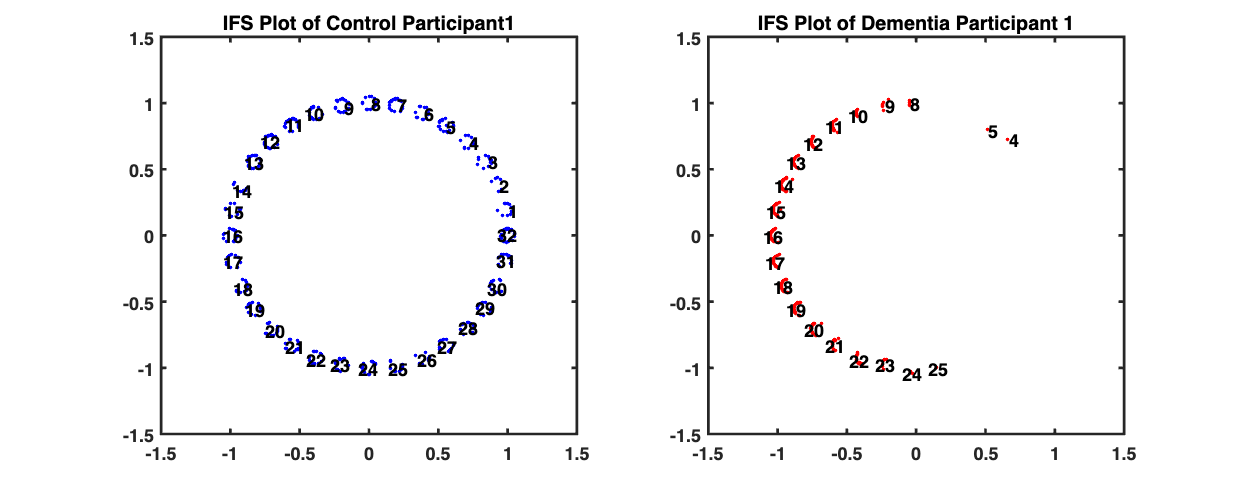

alpha = 0.05;
ifs_hc = IFS(x1(1,:),num_id,alpha);
ifs_ad = IFS(x2_new(1,:),num_id,alpha);
ifs_hc(1,:) = [];
ifs_ad(1,:) = [];

figure('Color','w','Position',[0,0,1400,550]);
subplot(1,2,1)
plot(ifs_hc(:,1),ifs_hc(:,2),'.','Color','b')
for i=1:num_id
    id_idx = find(x1(1,:) == i);
    c = mean(ifs_hc(id_idx,:),1);
    text(c(1)+0.08,c(2)+0.08,num2str(i),'FontWeight','bold',...
        'VerticalAlignment','top','HorizontalAlignment','right')
end
title('IFS Plot of Control Participant1')
set(gca,'LineWidth',1.5,'FontWeight','bold')
subplot(1,2,2)
plot(ifs_ad(:,1),ifs_ad(:,2),'.','Color','r')
for i=1:num_id
    id_idx = find(x2_new(1,:) == i);
    c = mean(ifs_ad(id_idx,:),1);
    text(c(1)+0.08,c(2)+0.08,num2str(i),'FontWeight','bold',...
        'VerticalAlignment','top','HorizontalAlignment','right')
end
xlim([-1.5,1.5])
title('IFS Plot of Dementia Participant 1')
set(gca,'LineWidth',1.5,'FontWeight','bold')

feat_mx = NaN(num_sig*2,32*3+32*32*3);

alpha = 0.04;
nbins = 0;

for i=1:num_sig   
    csig = x1(i,:);
    ifs_add = IFS(csig,num_id,alpha);
    
    % 1st order
    for j=1:num_id
        [feat_mx(i,j),feat_mx(i,j+num_id),feat_mx(i,j+num_id*2)] = ...
            heterorecurrence(ifs_add,csig,j,nbins);
        % 2nd order
        for k=1:num_id
            [feat_mx(i,k+96*j),feat_mx(i,k+96*j+num_id),feat_mx(i,k+96*j+num_id*2)] = ...
                heterorecurrence2(ifs_add,csig,j,k);
        end
    end
end

for i=1:num_sig
    csig = x2_new(i,:);
    ifs_add = IFS(csig,num_id,alpha);

    % 1st order
    for j=1:num_id
        [feat_mx(num_sig+i,j),feat_mx(num_sig+i,j+num_id),feat_mx(num_sig+i,j+num_id*2)] = ...
            heterorecurrence(ifs_add,csig,j,nbins);
        % 2nd order
        for k=1:num_id
            [feat_mx(num_sig+i,k+96*j),feat_mx(num_sig+i,k+96*j+num_id),feat_mx(num_sig+i,k+96*j+num_id*2)] = ...
                heterorecurrence2(ifs_add,csig,j,k);
        end
    end
end

w = 1./(var(feat_mx)+eps);
[~,score,~,~,explained] = pca(feat_mx,'VariableWeights',w);

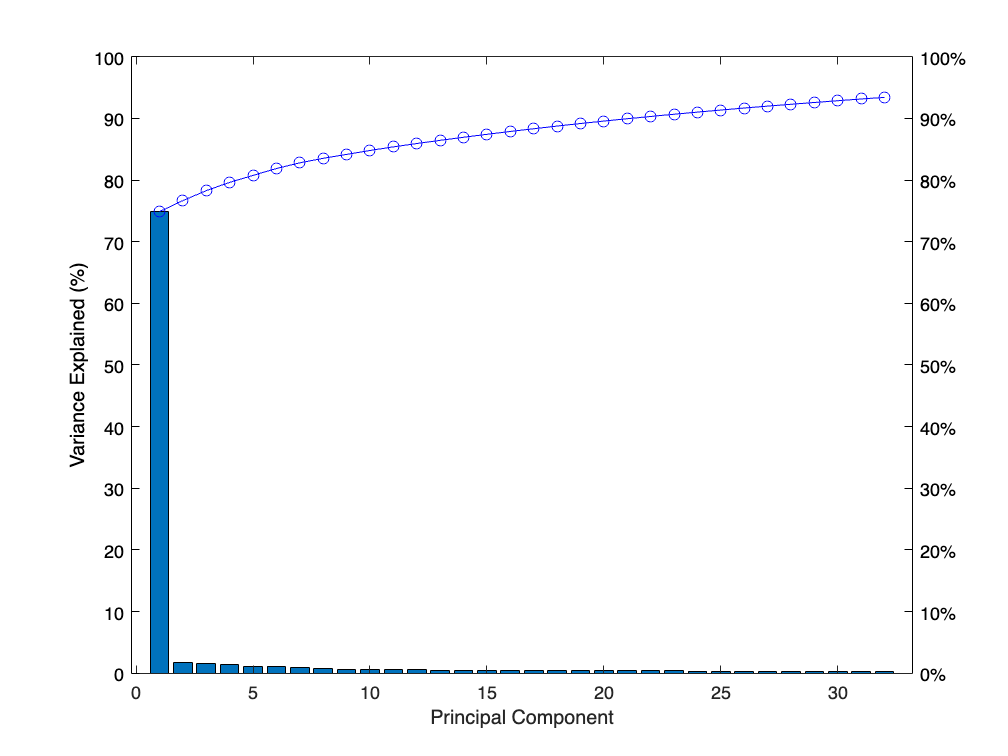

percent_ticks = string(0:10:100);
for i=1:length(percent_ticks)
    percent_ticks(i) = strcat(percent_ticks(i),"%");
end

figure
yyaxis left
bar(explained(1:num_id))
ylim([0,100])
set(get(gca,'YLabel'), 'String','Variance Explained (%)')
set(gca, 'YColor','black')
yyaxis right
plot(1:num_id,cumsum(explained(1:num_id)),'o-','Color','blue')
ylim([0,100])
yticklabels(percent_ticks)
set(gca, 'YColor','black')
xlabel('Principal Component')

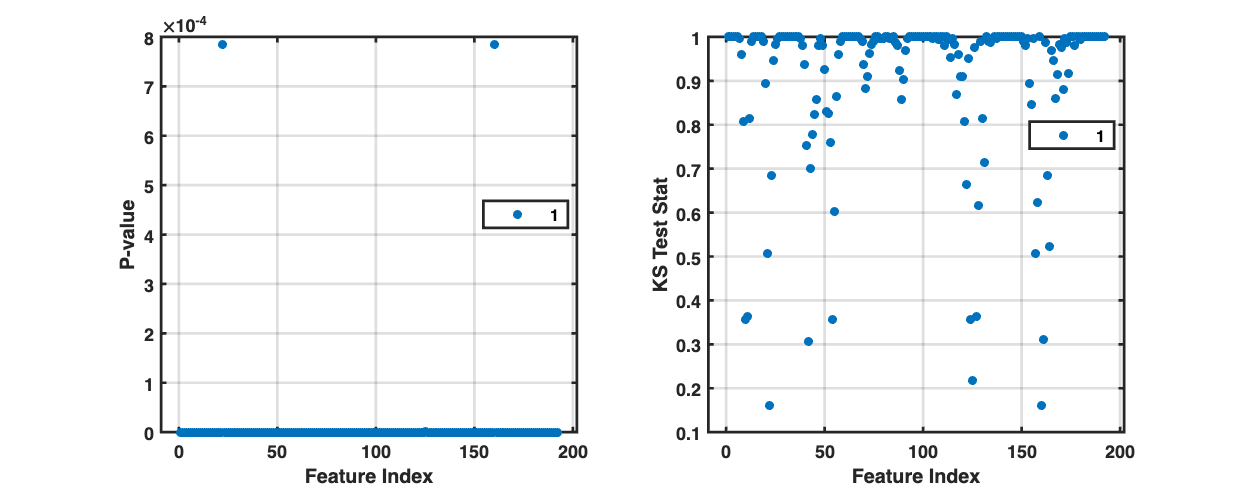

zidx = all(feat_mx==0,1);
feat_mx(:,zidx) = [];

out_mx = NaN(size(feat_mx,2),4);
out_mx(:,4) = find(~zidx)';
for i=1:size(feat_mx,2)
    [out_mx(i,1),out_mx(i,2),out_mx(i,3)] = kstest2(feat_mx(1:num_sig,i),feat_mx(num_sig+1:end,i), ...
        'Alpha',0.05,'Tail','unequal');
end

g = categorical(out_mx(:,1));
cidx = 1:size(feat_mx,2);

f = figure('Color','w','Position',[0,0,980,385]);
subplot(1,2,1)
gscatter(cidx,out_mx(:,2),g)
grid on
xlabel("Feature Index")
ylabel("P-value")
set(gca,'FontWeight','bold','LineWidth',1.5)

subplot(1,2,2)
gscatter(cidx,out_mx(:,3),g)
grid on
xlabel("Feature Index")
ylabel("KS Test Stat")
set(gca,'FontWeight','bold','LineWidth',1.5)

|======================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Lambda |
|      | result |             | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |           0 |      1.2897 |           0 |           0 |   8.8543e-05 |
|    2 | Accept |           0 |     0.38272 |           0 |           0 |       5.8631 |
|    3 | Accept |           0 |     0.29017 |           0 |           0 |     0.017248 |
|    4 | Accept |           0 |     0.12364 |           0 |           0 |   4.1816e-08 |
|    5 | Accept |           0 |     0.32792 |           0 |           0 |       205.81 |
|    6 | Accept |           0 |     0.15996 |           0 |           0 |       57.528 |
|    7 | Accept |           0 |     0.18879 |           0 |           0 |      0.10029 |
|    8 | Accept |    

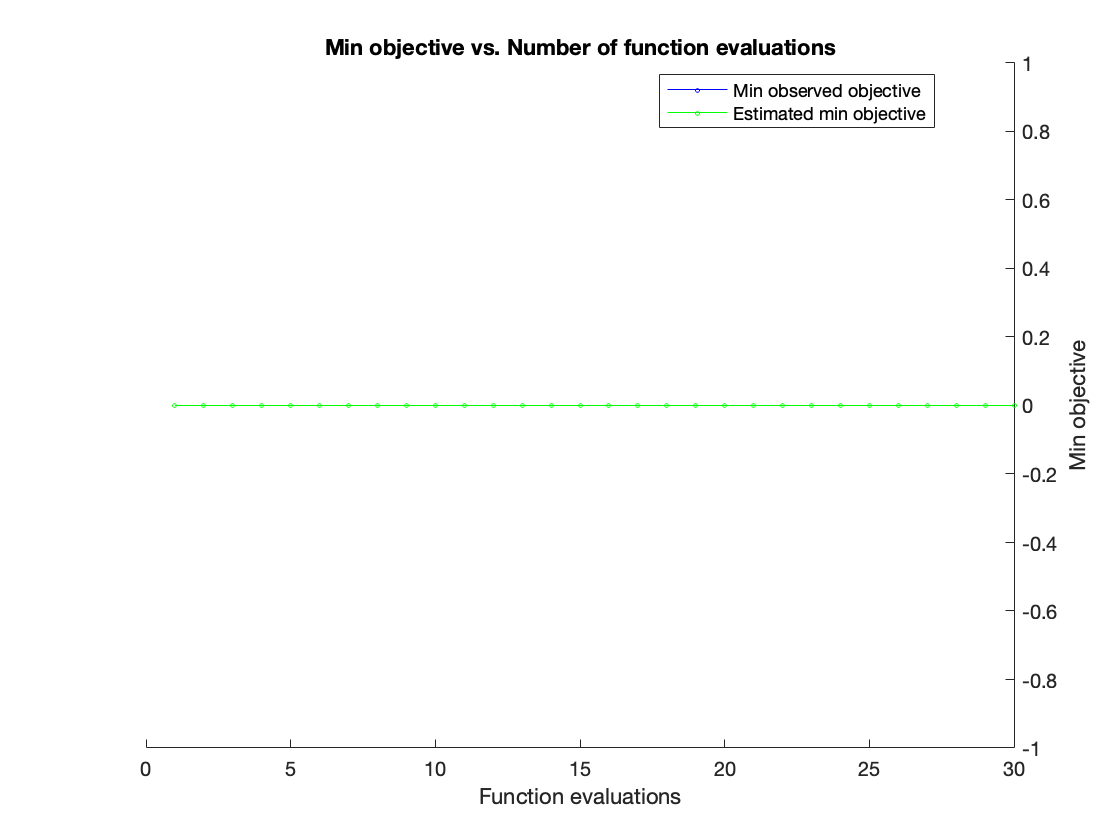

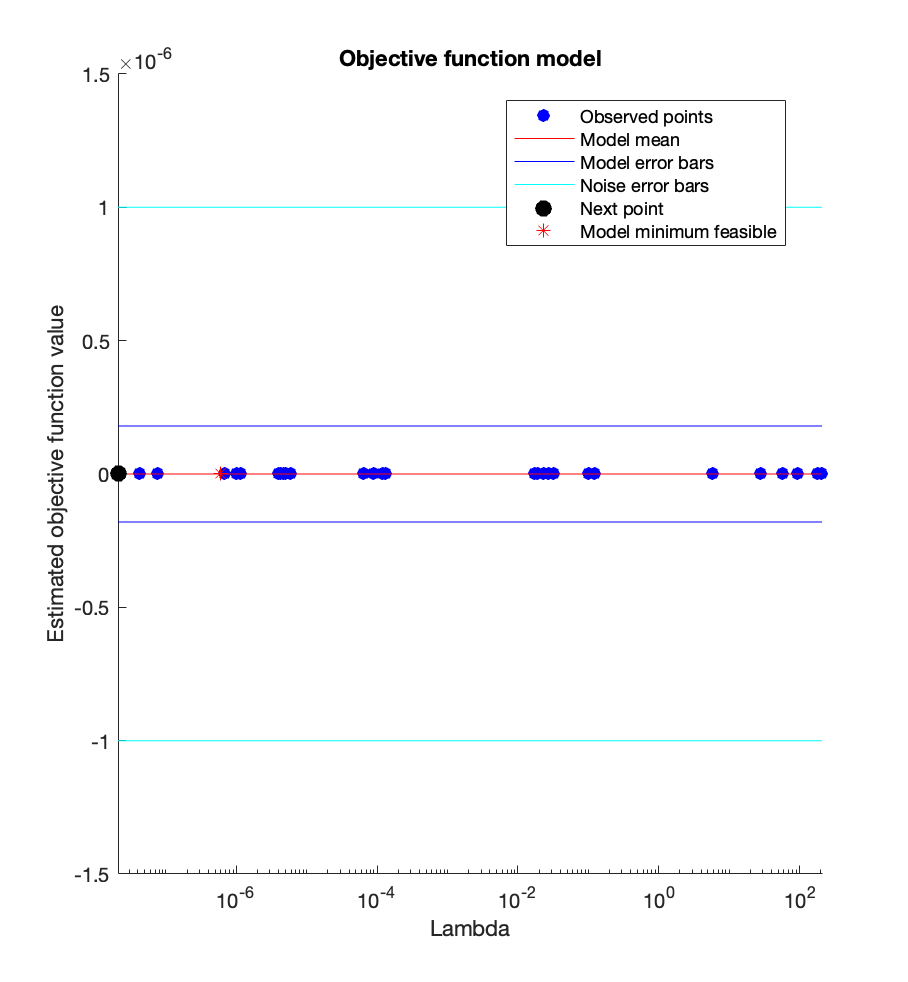


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 20.9947 seconds
Total objective function evaluation time: 6.1205

Best observed feasible point:
      Lambda  
    __________

    8.8543e-05

Observed objective function value = 0
Estimated objective function value = 0
Function evaluation time = 1.2897

Best estimated feasible point (according to models):
    Lambda 
    _______

    0.01703

Estimated objective function value = 0
Estimated function evaluation time = 0.19681



% feat_mx2 = feat_mx(:,out_mx(:,3) > quantile(out_mx(:,3),0.9));
ybool = zeros(size(feat_mx,1),1);
ybool(num_sig+1:end) = 1;
ybool = logical(ybool);

test_ratio = 0.2;
cv = cvpartition(ybool,'Holdout',test_ratio);
trn_idx = training(cv);
eval_idx = test(cv);

[mdl,fit_info] = fitclinear(feat_mx(trn_idx,:)',ybool(trn_idx),'ObservationsIn','columns',...
    'Learner','logistic',...
    'OptimizeHyperparameters',{'Lambda'},'HyperparameterOptimizationOptions',...
    struct('AcquisitionFunctionName','expected-improvement-plus'));


yhat = predict(mdl,feat_mx(eval_idx,:));
c = confusionmat(ybool(eval_idx),yhat);
disp(c)

    60     0
     0    60



statsOfMeasure(c,1);

stats = 9×4 table
          name          classes     macroAVG    microAVG
    ________________    ________    ________    ________

    "true_positive"     60    60       60          60   
    "false_positive"     0     0        0           0   
    "false_negative"     0     0        0           0   
    "true_negative"     60    60       60          60   
    "precision"          1     1        1           1   
    "sensitivity"        1     1        1           1   
    "specificity"        1     1        1           1   
    "accuracy"           1     1        1           1   
    "F-measure"          1     1        1           1   
